clear;clc;close all;

load('../data/NBAResults.mat');

x=[tbl_results.HomeScore;tbl_results.AwayScore];

得点の平均値と標準偏差

mu=mean(x)

mu = 99.5462

sgm=std(x)

sgm = 12.7988

- ポアソン分布は元データと同じ平均

- 正規分布は元データと同じ平均，および同じ標準偏差

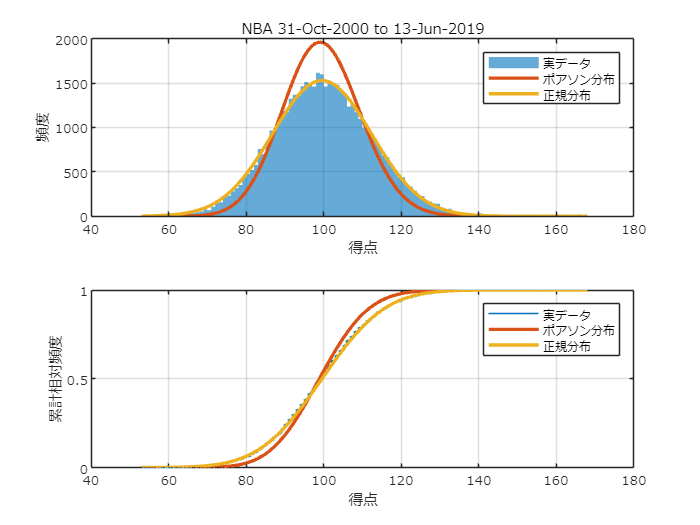

figure;
tiledlayout(2,1);
ax1=nexttile;
histogram(x,'EdgeAlpha',0);
grid on;hold on;
set(gca,'fontname','メイリオ');
xlabel('得点');ylabel('頻度');
title(['NBA ' datestr(min(tbl_results.Date)) ...
    ' to ' datestr(max(tbl_results.Date))])

pPoissonPdf=poisspdf(min(x):max(x),mu);
plot(min(x):max(x),pPoissonPdf*size(tbl_results,1)*2,'LineWidth',2);

pNormalPdf=normpdf(min(x):max(x),mu,sgm);
plot(min(x):max(x),pNormalPdf*size(tbl_results,1)*2,'LineWidth',2)

legend({'実データ','ポアソン分布','正規分布'})

ax2=nexttile;
ecdf(x);
grid on;hold on;
set(gca,'fontname','メイリオ');
xlabel('得点');ylabel('累計相対頻度');

pPoissonCdf=poisscdf(min(x):max(x),mu);
plot(min(x):max(x),pPoissonCdf,'LineWidth',2);

pNormalCdf=normcdf(min(x):max(x),mu,sgm);
plot(min(x):max(x),pNormalCdf,'LineWidth',2)

linkaxes([ax1,ax2],'x');
legend({'実データ','ポアソン分布','正規分布'})
exportgraphics(gcf,'fig_Exercise_Chap0504.pdf');